## Create grid

cla()
ax = gca();

%Create a 10 by 10 grid
xgrid = 0:1:10;
ygrid = 0:1:10;

% randomize x and y coordinates of start location
% variable a cooralates with x-coordinate
% min 1 and max 8
a = randi([1 8])

a = 7

% varaible b coralates with y-coordinate
b = randi([1 8])

b = 5


% x and y coordinates of the start location 
start_current_position = [a b]

start_current_position =      7     5



% display 10 by 10 grid
xl = arrayfun(@(x)xline(x,'k', "LineWidth",2), xgrid);
yl = arrayfun(@(y)yline(y,'k','LineWidth',2), ygrid);
hold on
% display green start location on grid 
ml = arrayfun(@(x)xline(x,'k', "LineWidth",2),xgrid), (rectangle('Position',[a,b,1,1],'FaceColor','g'));

ml =   1×11 ConstantLine array:

    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine


nl = arrayfun(@(y)yline(y,'k','LineWidth',2),ygrid,'UniformOutput', false), (rectangle('Position',[a,b,1,1],'FaceColor','g'));

nl = 1×11 cell array
    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}


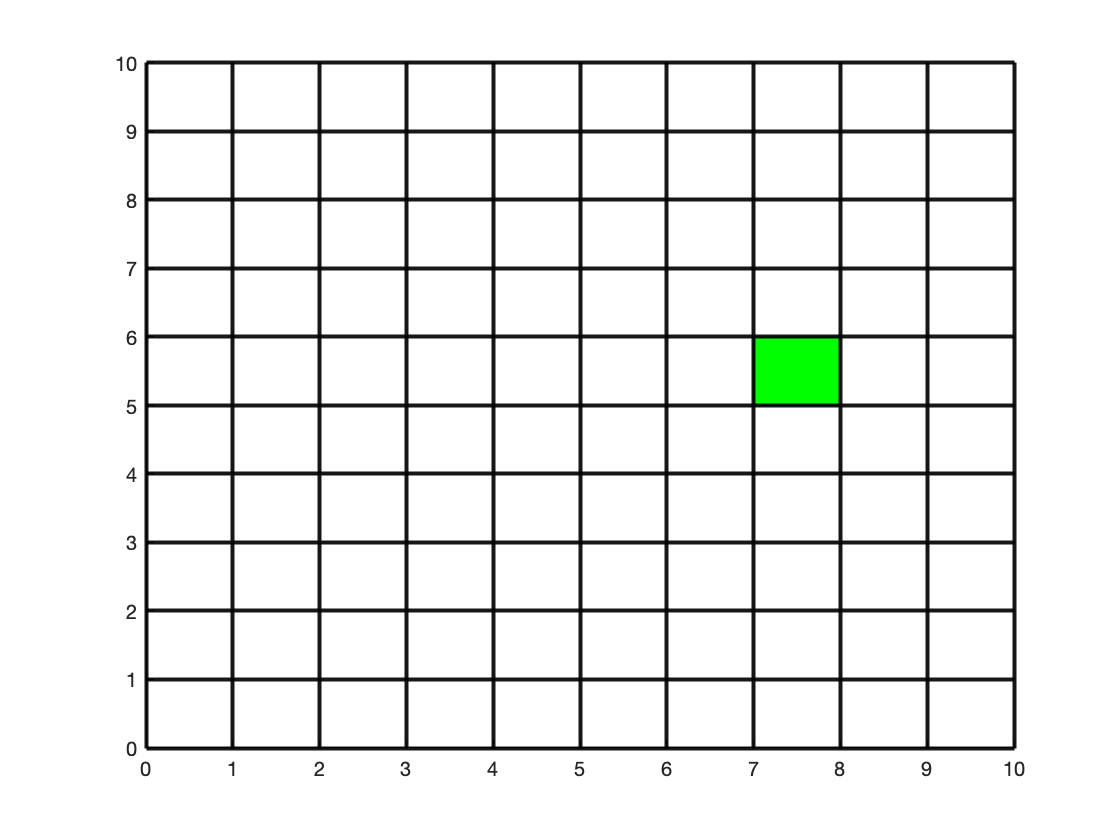

hold on

## Direction types & randomize directions



%Direction types
% These variables are not used within the code
% They are reference to what the direction types are
N = [0,1];
E = [1,0];
S = [0,-1];
W = [-1,0];

% This if statement starts the path of maze based off
% of the starting grid location

% when the x, y coordinates are on the bounds of the grid
% Then it can only go a certain direction
if a == 9 && b == 9 
% uses datasample to randomize direction types based on where the path can 
% contiune on to next
% 1 -> north
% 2 -> east
% 3 -> south
% 4 -> west
rand_dirc = datasample([1 2 3 4],1,"Weights",[0, 0, 0.50, 0.50])
elseif a == 0
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.33, 0.33, 0.33, 0])
elseif b == 0
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.33, 0.33, 0, 0.33])
elseif a == 0 && b == 0
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.50, 0.50, 0, 0])
elseif a == 9
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.33, 0, 0.33, 0.33])
elseif b == 9
rand_dirc = datasample([1 2 3 4],1,"Weights",[0, 0.33, 0.33, 0.33])
elseif a == 9 && b == 0
rand_dirc = datasameple([1 2 3 4],1,"Weights",[0, 0, 0.50, 0.50])
elseif a == 0 && b == 9
rand_dirc = datasample([1 2 3 4],1,"Weights",[0, 0.50, 0.50, 0])
% When the start location is not on the outer bounds
% can equally randomize the direction of the start grid path
elseif a ~= 9 || a~= 0 && b ~= 9 || b ~= 0 
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.25, 0.25, 0.25, 0.25])
end

rand_dirc = 3


% North
if rand_dirc == 1
new = [a+0, b+1]
% East
elseif rand_dirc == 2
new = [a+1, b+0]
% South
elseif rand_dirc == 3
new = [a+0, b-1]
% west
elseif rand_dirc == 4
new = [a-1, b+0]
end

new =      7     4


% Assign new variable to "new"
new_scpos = new

new_scpos =      7     4


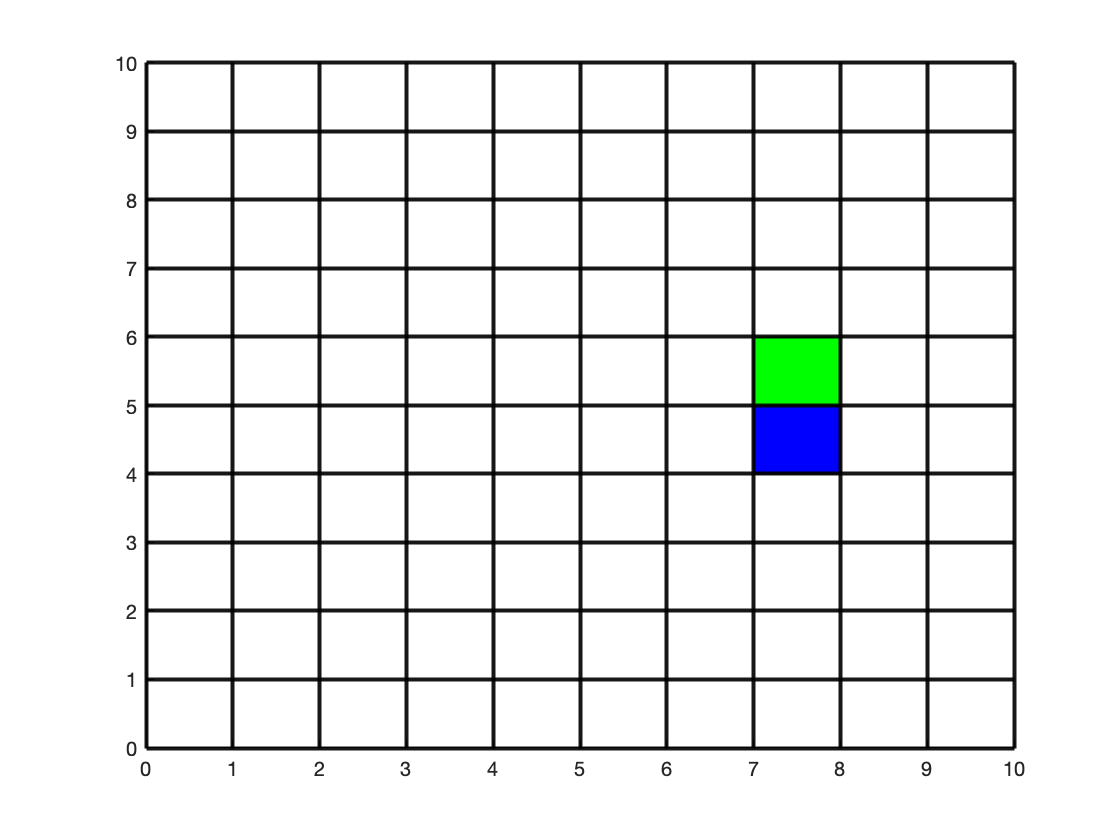


%Create the starting maze path on the grid 
% which is blue
path = rectangle('Position',[new_scpos,1,1], 'FaceColor','b');
hold on

% assign new varible 'p' to current x,y coordinates
p = new_scpos

p =      7     4


## Create path



%Number of turns
num_turns = 5;
%total path length
path_length = 10;
%The total number of segment lengths
Max_lengths = num_turns+1;

% what the variable of c means: (broken down below)

% (randi([0,path_length-Max_lengths],1,Max_lengths-1))
    %Returns size [1xMax_lengths-1] vector of random integers
    %Between 0 and path_length - Max_lengths

%sort the output of the randi array in order from ascending order
    % returns [1xMax_lengths-1] vector of sorted random values in ascending
    % order

%find the diff of ([ 0, sorted ouput, pth_length - max_length])
    % returns [ 1 x max_length] vector of segment legnths
    % will find the difference between each element in vector

% +ones(1,Max_lengths)
    % returns [ 1 x max_length] vector of segment lenghts
    % adds the [ 1 x max_lengths] vector to the vector of difference values

c = (diff([0,sort(randi([0,path_length-Max_lengths],1,Max_lengths-1)),path_length-Max_lengths])+ones(1,Max_lengths))

c =      1     3     3     1     1     1




% assign new varible to p
% in order to update the new coordinates of maze path
new_path_dirc = p

new_path_dirc =      7     4


% update the value of p from startiing grid path location
p = new_scpos

p =      7     4


c =      0     3     3     1     1     1


p =      7     4


dirc = 2

new_path_dirc2 =      8     4


p =      8     4


rand_dirc = 2

p =      8     4


c =      0     2     3     1     1     1


new_path_dirc =      9     4


p =      9     4


c =      0     1     3     1     1     1


new_path_dirc =     10     4


rand_dirc = 4

new_path_dirc =      8     4


c =      0     0     3     1     1     1


p =      8     4


dirc = 1

new_path_dirc2 =      8     5


p =      8     5


rand_dirc = 1

p =      8     5


c =      0     0     2     1     1     1


new_path_dirc =      8     6


p =      8     6


c =      0     0     1     1     1     1


new_path_dirc =      8     7


c =      0     0     0     1     1     1


p =      8     7


dirc = 4

new_path_dirc2 =      7     7


p =      7     7


rand_dirc = 4

c =      0     0     0     0     1     1


p =      7     7


dirc = 1

new_path_dirc2 =      7     8


p =      7     8


rand_dirc = 1

c =      0     0     0     0     0     1


p =      7     8


dirc = 4

new_path_dirc2 =      6     8


p =      6     8


rand_dirc = 4

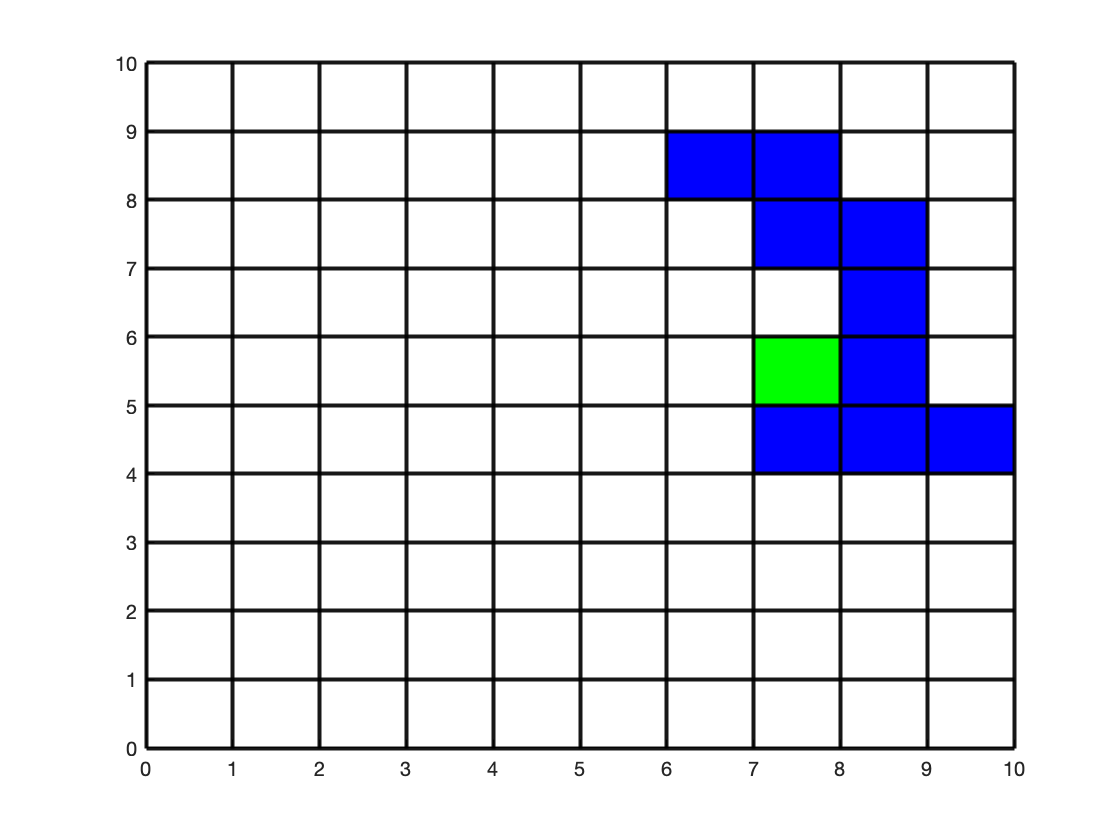

% iterate through the length of c
for i = 1:length(c)
% analyze each individual element of 'c' array
for ii = 1:c(i)
% When the individual element of 'c' is greater than one
% create the path, WHEN ITS NOT A TURN
if c(i) > 1

%update the value of variable of p
p = new_path_dirc

% substract that individual element by one
c(i) = c(i) - 1 

% p(1) -> x coordinate of maze path
% p(2) -> y coordinate of maze path
% new_path_dirc -> new x,y coordinates used to create the maze on grid

% contuine to create path in north direction
if rand_dirc == 1 
new_path_dirc = [p(1)+0, p(2)+1]
end
% contuine to create path in east direction
if rand_dirc == 2
new_path_dirc = [p(1)+1, p(2)+0]
end
% contuine to create path in south direction
if rand_dirc == 3
new_path_dirc = [p(1)+0, p(2)-1]
end
% contuine to create path in west direction
if rand_dirc == 4
new_path_dirc = [p(1)-1, p(2)+0]
end


% when the path coordinates are on the outer bounds of grid
while new_path_dirc(1) < 0 || new_path_dirc(1) > 9 || new_path_dirc(2) < 0 || new_path_dirc(2) > 9 %|| p(1) == a && p(2) == b
% change path direction in order to stay within the grid
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.25, 0.25, 0.25, 0.25])
% create path in north direction
if rand_dirc == 1 
new_path_dirc = [p(1)+0, p(2)+1]
end
% create path in east direction
if rand_dirc == 2
new_path_dirc = [p(1)+1, p(2)+0]
end
% create path in south direction
if rand_dirc == 3
new_path_dirc = [p(1)+0, p(2)-1]
end
% create path in west direction
if rand_dirc == 4
new_path_dirc = [p(1)-1, p(2)+0]
end

end
% create maze path on the grid
rectangle('Position',[new_path_dirc,1,1], 'FaceColor','b');
end

% When the element in array c is 1 and not the last segment
% Craete a TURN
if c(i) == 1 && i ~= Max_lengths
% decrease the elements in array c by one
c(i) = c(i) - 1 
% update the value of p
p = new_path_dirc

% change direction E W
% when direction of path is either going north or south

% new_path_dirc(1) -> x coordinate of maze path @ turn
% new_path_dirc(2) -> y coordinate of maze path @ turn
% new_path-dirc2 -> new x, y coordinates of maze path @ turn

if rand_dirc == 1 || rand_dirc == 3
% randomly chooses between going east or west
dirc = datasample([1 2 3 4],1,"Weights",[0 0.50 0 0.50])
if dirc == 2 % east
new_path_dirc2 = [new_path_dirc(1)+1, new_path_dirc(2)+0]
elseif dirc == 4 % west
new_path_dirc2 = [new_path_dirc(1)-1, new_path_dirc(2)+0]
end
% update the value of varibale p (coordiantes of the path)
p = new_path_dirc2 
% update the value of variable rand-dirc (path direction of the maze)
rand_dirc = dirc
% update the value of variable new_path_dirc
new_path_dirc = p;

% change direction N S
% when direction of path is either going east or west
elseif rand_dirc == 2 || rand_dirc == 4
% randomly choose between going north or south
dirc = datasample([1 2 3 4],1,"Weights",[0.50 0 0.50 0])
if dirc == 1 % north
new_path_dirc2 = [new_path_dirc(1)+0, new_path_dirc(2)+1]
elseif dirc == 3 % south
new_path_dirc2 = [new_path_dirc(1)+0, new_path_dirc(2)-1]
end
% update the value of variable p (coordiantes of the path)
p = new_path_dirc2
% update the value of variable rand_dirc (path direction of the maze)
rand_dirc = dirc
% update the value of variable new_path_dirc
new_path_dirc = p;
end

% When the path is on the outer bounds of grid
% choose new direction to go to stay within the bounds of the grid
% WHEN AT A TURN
while new_path_dirc2(1) < 0 || new_path_dirc2(1) > 9 || new_path_dirc2(2) < 0 || new_path_dirc2(2) > 9 
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.25, 0.25, 0.25, 0.25])

%change direction E W
% when direction of path is either going north or south

% update the value of variable of p
p = new_path_dirc
if rand_dirc == 1 || rand_dirc == 3
% randomly choose between going east or west
dirc = datasample([1 2 3 4],1,"Weights",[0 0.50 0 0.50])
if dirc == 2 % east
new_path_dirc2 = [new_path_dirc(1)+1, new_path_dirc(2)+0]
elseif dirc == 4 % west
new_path_dirc2 = [new_path_dirc(1)-1, new_path_dirc(2)+0]
end
% update the value of variable p (coordiantes of the path)
p = new_path_dirc2 
% update the value of variable rand_dirc (path direction of maze)
rand_dirc = dirc
% update the value of variable new_path_dirc
new_path_dirc = p;

% change direction N S
% when direction of path is either going east or west
elseif rand_dirc == 2 || rand_dirc == 4
% randomly choose between going north or south
dirc = datasample([1 2 3 4],1,"Weights",[0.50 0 0.50 0])
if dirc == 1 % north
new_path_dirc2 = [new_path_dirc(1)+0, new_path_dirc(2)+1]
elseif dirc == 3 % south
new_path_dirc2 = [new_path_dirc(1)+0, new_path_dirc(2)-1]
end
% update the value of variable p (coordiantes of the path)
p = new_path_dirc2
% update the value of variable rand_dirc (path direction of maze)
rand_dirc = dirc
% update the value of variable new_path_dirc
new_path_dirc = p;
end

end
% creates the path of maze on the grid
rectangle('Position',[new_path_dirc2,1,1], 'FaceColor','b')

end


end
end

## Finish area


% create the finish grid area
% This at the movement is seperate from the for loop of the path
% therefore will go off thr grid

% update the value of variable new_path_dirc
new_path_dirc2 = new_path_dirc

new_path_dirc2 =      6     8


finish_location =      5     8


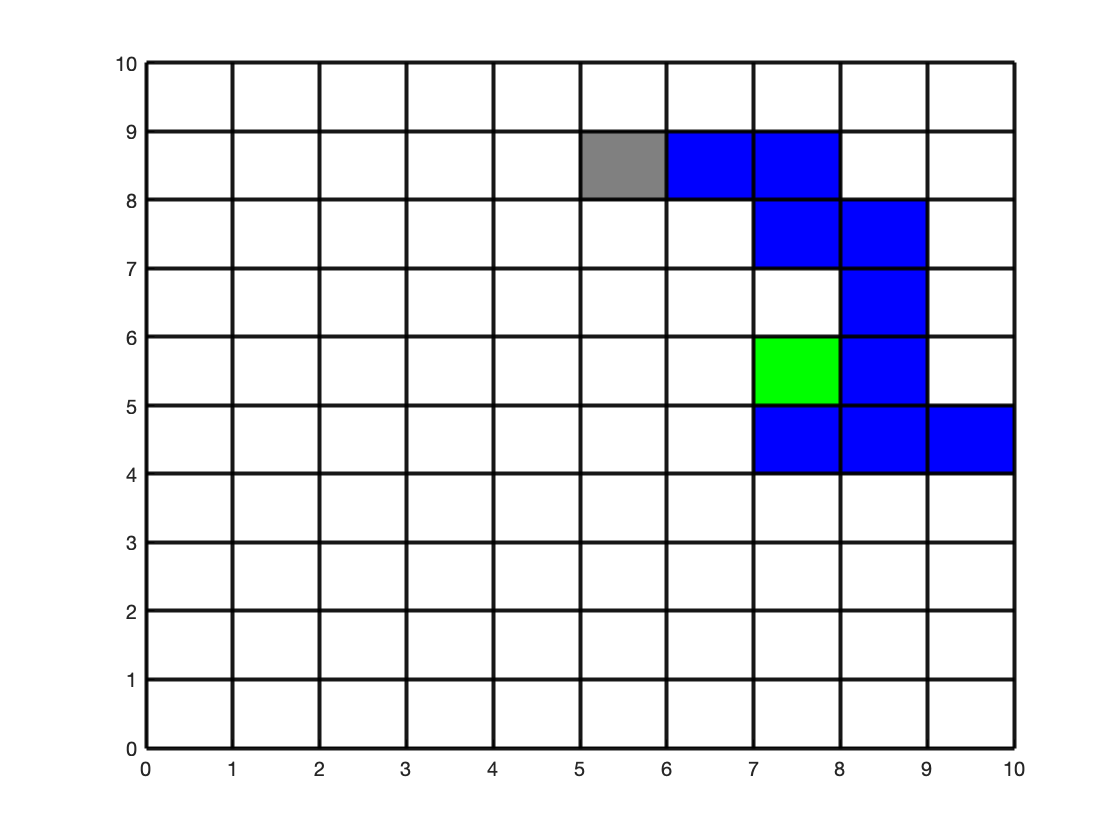


if rand_dirc == 1 %north
finish_location = [new_path_dirc2(1)+0, new_path_dirc2(2)+1]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
elseif rand_dirc == 2 % east
finish_location = [new_path_dirc2(1)+1, new_path_dirc2(2)+0]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
elseif rand_dirc == 3 % west
finish_location = [new_path_dirc2(1)+0, new_path_dirc2(2)-1]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
elseif rand_dirc == 4 % south
finish_location = [new_path_dirc2(1)-1, new_path_dirc2(2)+0]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
end   